# Loading data

samFr = load('/Users/karimvafin/Downloads/Lab3/data/samplingFrequency.txt');
vFW = load('/Users/karimvafin/Downloads/Lab3/data/volumeFractionWater.txt');
temp = load('/Users/karimvafin/Downloads/Lab3/data/temperature.txt');
airRaw = load('/Users/karimvafin/Downloads/Lab3/data/air.txt');
breathRaw = load('/Users/karimvafin/Downloads/Lab3/data/breath.txt');
time = load('/Users/karimvafin/Downloads/Lab3/data/totalTime.txt');

Time = linspace(0, time, samFr*time + 1)';

%%Normalization

windowSize = 5;
b = (1 / windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
tt = Time(start:end);

cAir = polyfit(tt, airFiltered(:, 1), 3);
cBreath = polyfit(tt, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, tt);
airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, tt);
breathNorm = breath ./ max(breath);

%%Calculation of velocity

air1 = airNorm(:, 1);
air2 = airNorm(:, 2);

breath1 = breathNorm(:, 1);
breath2 = breathNorm(:, 2);

f1 = figure;
figure(f1);

plot(tt, air1, 'b');
hold on;
grid on;
plot(tt, air2, 'r');

xlabel('Время, c');
ylabel('Отсчеты АЦП');
legend('Микрофон 1', 'Микрофон 2');
title('Относительное изменение давления у микрофонов в воздухе');

dt1 = tt(air2 == max(air2)) - tt(air1 == max(air1));
v1 = 1.158 / dt1

v1 = 345.6716

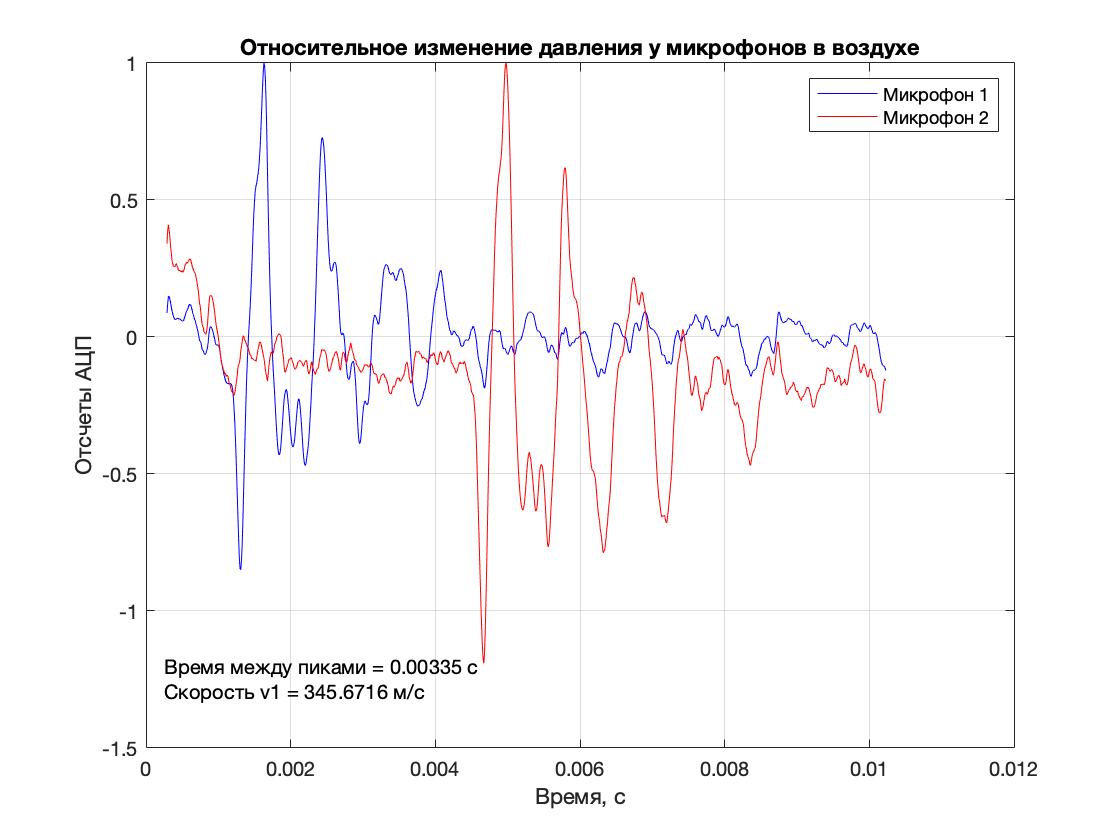


str1 = ['Время между пиками = ' num2str(dt1) ' c'];
str2 = ['Скорость v1 = ' num2str(v1) ' м/с'];
text(0.00025, -1.25, {str1, str2});
saveas(f1, 'pressure1.png');


f2 = figure;
figure(f2);

hold off;

plot(tt, breath1, 'b');
hold on;
grid on;
plot(tt, breath2, 'r');

xlabel('Время, c');
ylabel('Отсчеты АЦП');
legend('Микрофон 1', 'Микрофон 2');
title('Относительное изменение давления у микрофонов в воздухе из легких');

dt2 = tt(breath2 == max(breath2)) - tt(breath1 == max(breath1));
v2 = 1.158 / dt2

v2 = 344.6429

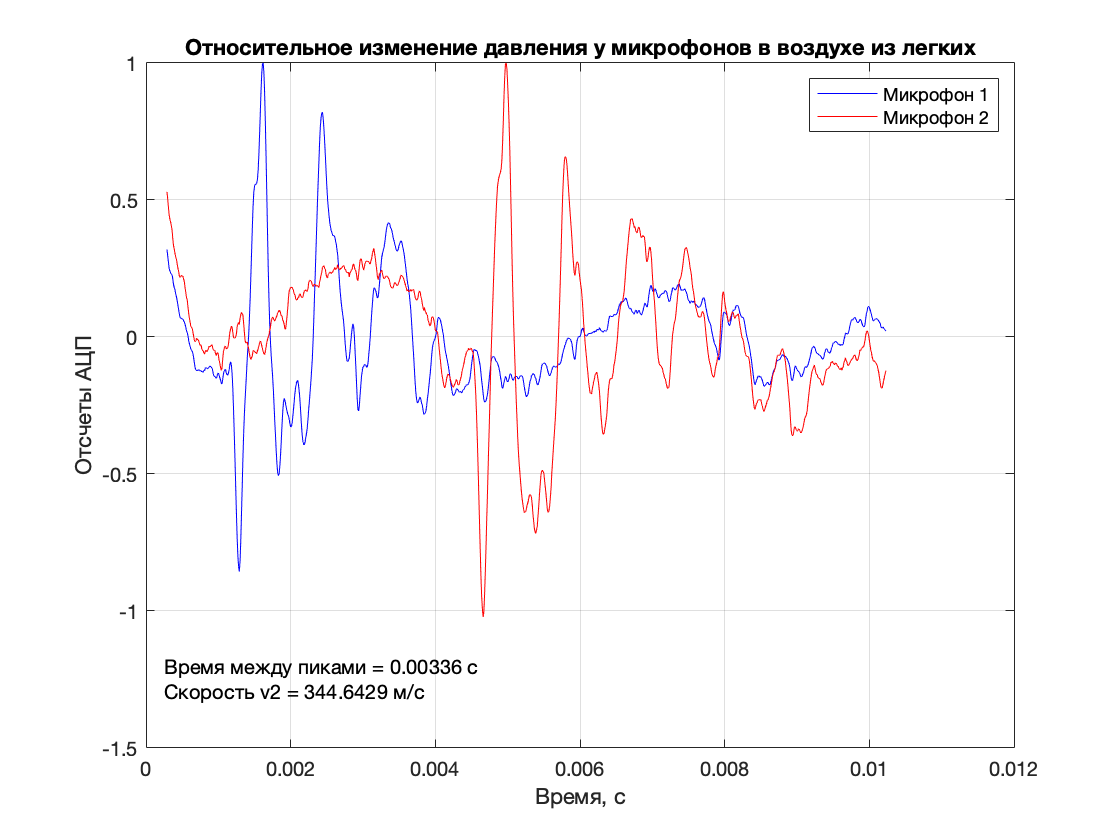


str3 = ['Время между пиками = ' num2str(dt2) ' c'];
str4 = ['Скорость v2 = ' num2str(v2) ' м/с'];
text(0.00025, -1.25, {str3, str4});

saveas(f2, 'pressure2.png');

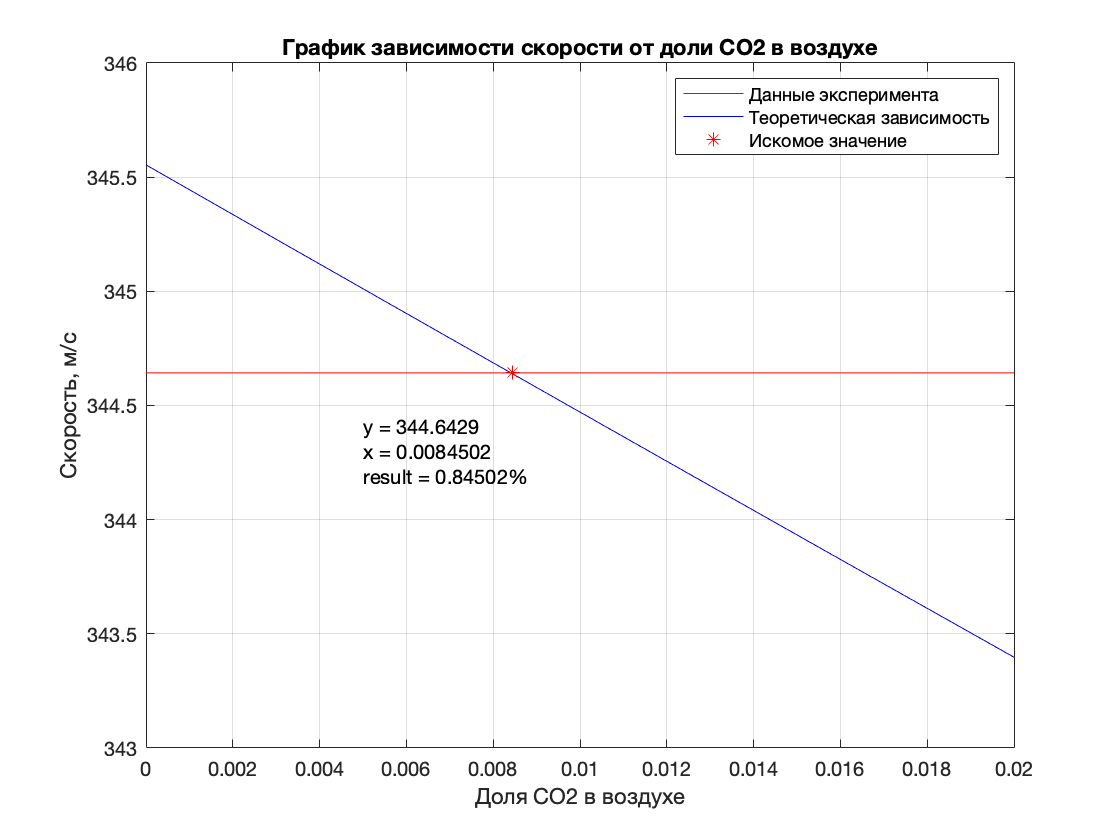

%%Dependence between sound velocity and CO2

mu1 = 0.02897;
mu2 = 0.01801;
mu3 = 0.04401;

cp1 = 1.0036;
cp2 = 1.863;
cp3 = 0.838;

cv1 = 0.7166;
cv2 = 1.403;
cv3 = 0.649;

x = linspace(0, 0.02, 1000);
v2vect = v2*ones(1, 1000);

mu = mu1*(1 - x - vFW) + mu2*vFW + mu3*x;
gamma = (mu1*cp1*(1 - x - vFW) + mu2*cp2*vFW + mu3*cp3*x)./(mu1*cv1*(1 - x - vFW) + mu2*cv2*vFW + mu3*cv3*x);

velocity = gamma.*8.314;
velocity = velocity.*(temp+273);
velocity = velocity./mu;
velocity = sqrt(velocity);

f3 = figure;
figure(f3);

hold off;

plot(x, v2vect, 'r');
hold on;
grid on;
plot(x, velocity, 'b');
xlabel('Доля СО2 в воздухе');
ylabel('Скорость, м/с');
title('График зависимости скорости от доли CO2 в воздухе');

result = (v2 - max(velocity))/(min(velocity) - max(velocity))*max(x);
plot(result, v2, 'r*');
legend('Данные эксперимента', 'Теоретическая зависимость', 'Искомое значение');

text(0.005, 344.3, {['y = ' num2str(v2)] ['x = ' num2str(result)] ['result = ' num2str(result*100) '%']});

saveas(f3, 'result.png');